# EPC 8 - Estatística Aplicada

## João Gabriel Santos Custodio

load("dad8.mat")
m = 18;
n = 100;

1) Obtenha a matriz de covariância S de X, plote seus autovalores em um gráficos de barras, comparando a variância total de X com a soma dos autovalores de S.

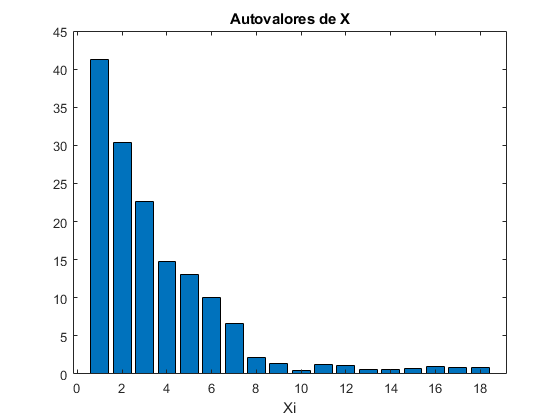

S = 1/(100-1).*transpose(X)*X;
autovalores_S = eig(S);
figure(1)
bar(1:1:18,autovalores_S)
title("Autovalores de X")
xlabel("Xi")

sum_a = sum(autovalores_S);
diagonal_S = zeros(1,18);
for i = 1:1:18
 diagonal_S(i) = S(i,i) ;
end
sum_var = sum(diagonal_S);

display("A soma dos autovalores de S é "+ sum_a)

    "A soma dos autovalores de S é 149.4703"



display("a variância total de X é "+ sum_var)

    "a variância total de X é 149.4703"



Resposta:Uma vez que os valores ao longo da diagonal principal da matriz S correspondem às variâncias das colunas na matriz X, a soma desses valores deve equivaler à soma dos autovalores de S. Esses autovalores refletem as variações dos autovetores, cuja soma, por sua vez, representa a variância total observada em X.

2) Faça o gráfico de soma cumulativa dos autovalores de S normalizados em 100%, de modo a mostrar a relação entre a soma dos autovalores e a variância retida pelas componentes principais. Qual o número de componentes que deve-se manter para reter pelo menos 70% da variância de X? 

Cálculo dos autovalores presentes na matriz L que correspondem aos autovetores presentes na matriz V:

[V, L] = eig(S) 

V =    -0.4658   -0.3532    0.0014    0.4282   -0.1903   -0.4187    0.4854   -0.1459    0.0244   -0.0374    0.0393   -0.0010    0.0371    0.0085   -0.0150    0.0250   -0.0237   -0.0002
   -0.6221   -0.4282    0.1360   -0.4142   -0.1438    0.3690   -0.2654    0.0567    0.0591   -0.0064    0.0020    0.0043   -0.0460    0.0478    0.0008   -0.0212   -0.0200    0.0183
    0.1545   -0.3694    0.6267    0.1601    0.4670   -0.2614   -0.3360   -0.0893   -0.0124   -0.0486    0.0474   -0.0071   -0.0062   -0.0441    0.0278   -0.0543   -0.0241   -0.0546
    0.4703   -0.5245   -0.1229   -0.1091   -0.0651    0.3564    0.2806   -0.4865    0.0432   -0.0609    0.0119    0.0082    0.0667    0.0125    0.0325    0.0774   -0.1100   -0.0218
    0.1016   -0.3871   -0.4697    0.5339   -0.0040    0.1610   -0.3932    0.3635   -0.0466    0.0460    0.0075   -0.0191   -0.0297   -0.0031    0.0160   -0.0171    0.1060    0.0644
   -0.3267    0.0918   -0.4057   -0.0005    0.7872    0.1236    0.0875   -0.2515   -0.0069 

L =    41.1957         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   30.3209         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   22.5850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   14.7565         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0   13.0881         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    9.9767         0         0         0 

Observa-se maior contribuição nos primeiros autovalores.

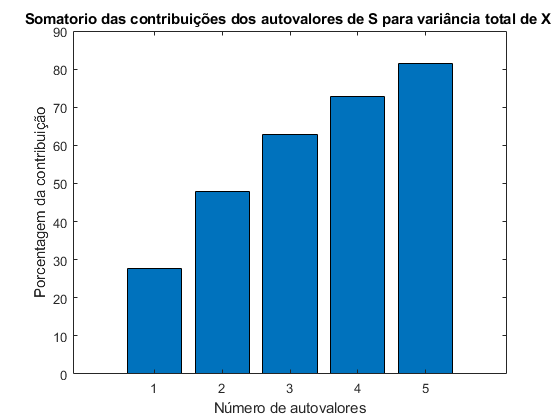

auto_cum = cumsum(autovalores_S(1:5)/sum(autovalores_S))*100; 
bar(1:1:5,auto_cum)
xlabel("Número de autovalores")
ylabel("Porcentagem da contribuição")
title("Somatorio das contribuições dos autovalores de S para variância total de X ") 

Resposta:

A partir do gráfico acima vemos que com 4 autovalores de S já é possível estimar 70% da variância total de X, definndo que essas são as parcelas que tem maior contribuição para a estatístca total. 

3) Plote a estimativa da primeira variável de X (X(:,1)) obtida usando as componentes principais retidas na atividade 2, comparando com seu valor original.

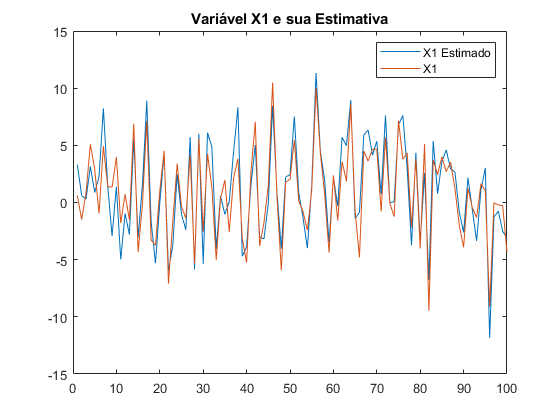

P = [V(:,1:5)];
T = X*P;
X_est = T*P';
figure
plot(1:1:100,X(:,1))
hold on
plot(1:1:100,X_est(:,1))
legend("X1 Estimado","X1")
title("Variável X1 e sua Estimativa")

Resposta: A análise do gráfico revela que a estimativa de x1 foi eficaz, contudo, é evidente que essa abordagem se mostra restrita quanto à reprodução totalmente fiel do comportamento real da variável. Isso ocorre devido à utilização exclusiva das componentes principais da variância total de X

4) Calcule a estatística usando X e o número a de componentes que mantêm pelo menos 70% da variância de X. Plote esta estatística junto com os limiares obtidos pelas distribuições F e chi-quadrado. Use nível de confiança de 95%, e quantifique os falsos positivos. 

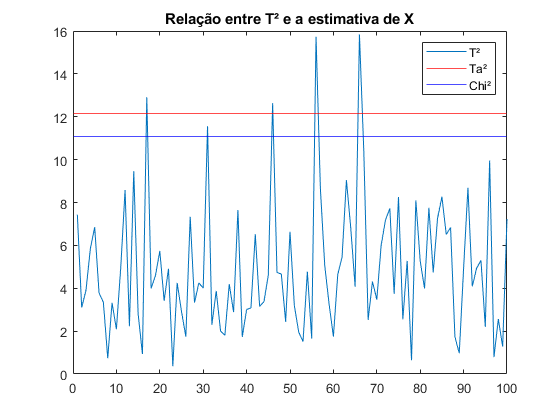

a = 5;
Ta2 = (a*(n-1)*(n+1))/(n*(n-a))*finv(0.95,a,n-a);
chi2 = chi2inv(0.95,a);
t2 = zeros(1,n);
Si = inv(S);
for i = 1:1:n
 t2(i) = X_est(i,:)*Si*X_est(i,:)';
end
figure
plot(1:1:n,t2)
hold on
yline(Ta2,"r")
yline(chi2,"b")
legend("T²", "Ta²", "Chi²")
title("Relação entre T² e a estimativa de X") 


f_pt2 = 0;
f_pchi2 = 0;
for i = 1:1:n
 if t2(i)>chi2
 f_pchi2 = f_pchi2+1;
end
if t2(i)>Ta2
 f_pt2 = 1+ f_pt2;
end
end
display("Aconteceram um total de "+ f_pchi2+ " falsos positivos para o limiar de Chi², e " + f_pt2+ " para o limiar de Ta²") 

    "Aconteceram um total de 5 falsos positivos para o limiar de Chi², e 4 para o limiar de Ta²"



Resposta: 

Ao examinar as verificações de falsos positivos, constatamos que a estatística T² para a estimativa de X foi realizada de maneira eficiente, resultando na detecção de apenas alguns casos de falsos positivos.

5) Use a matriz de covariância e o limiar F do item 4 para detectar as falhas nos dados de teste Y, medindo o recall e o tempo de detecção. Nestes dados, todas as amostras são de falha. Caso estas métricas fiquem muito ruins (recall bem menor de 95%), escolha um número diferente de componentes principais e refaça a detecção. 

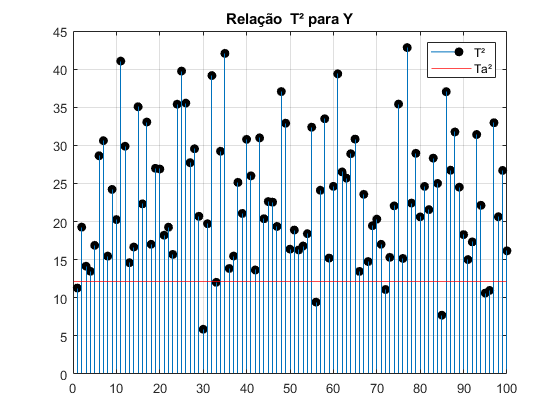

T = Y*P;
Y_est = T*P';
for i = 1:1:n
 t2(i) = Y_est(i,:)*(Si)*Y_est(i,:)'; 
end
figure

stem(1:1:n,t2,"MarkerFaceColor","black","MarkerEdgeColor","black") 
grid on
hold on
yline(Ta2,"r")
legend("T²", "Ta²")
title("Relação  T² para Y") 


TP = length(find(t2 > Ta2));
FN = length(find(t2 <= Ta2));
recall = TP/(TP+FN);
td = find(t2 > Ta2);
td = td(1);
display("Recall é "+ recall)

    "Recall é 0.92"



display("tempo de detecção é de " +td+" amostras.") 

    "tempo de detecção é de 2 amostras."



Resposta:

Os índices apresentados indicam uma eficaz identificação das falhas no conjunto Y ao utilizar a estimativa com base na matriz de covariância de X.